# Closed-Loop Position Control of a Tank System: the Case of a Sampled-Time PI Control Law 

## System Description

Consider the hydraulic system

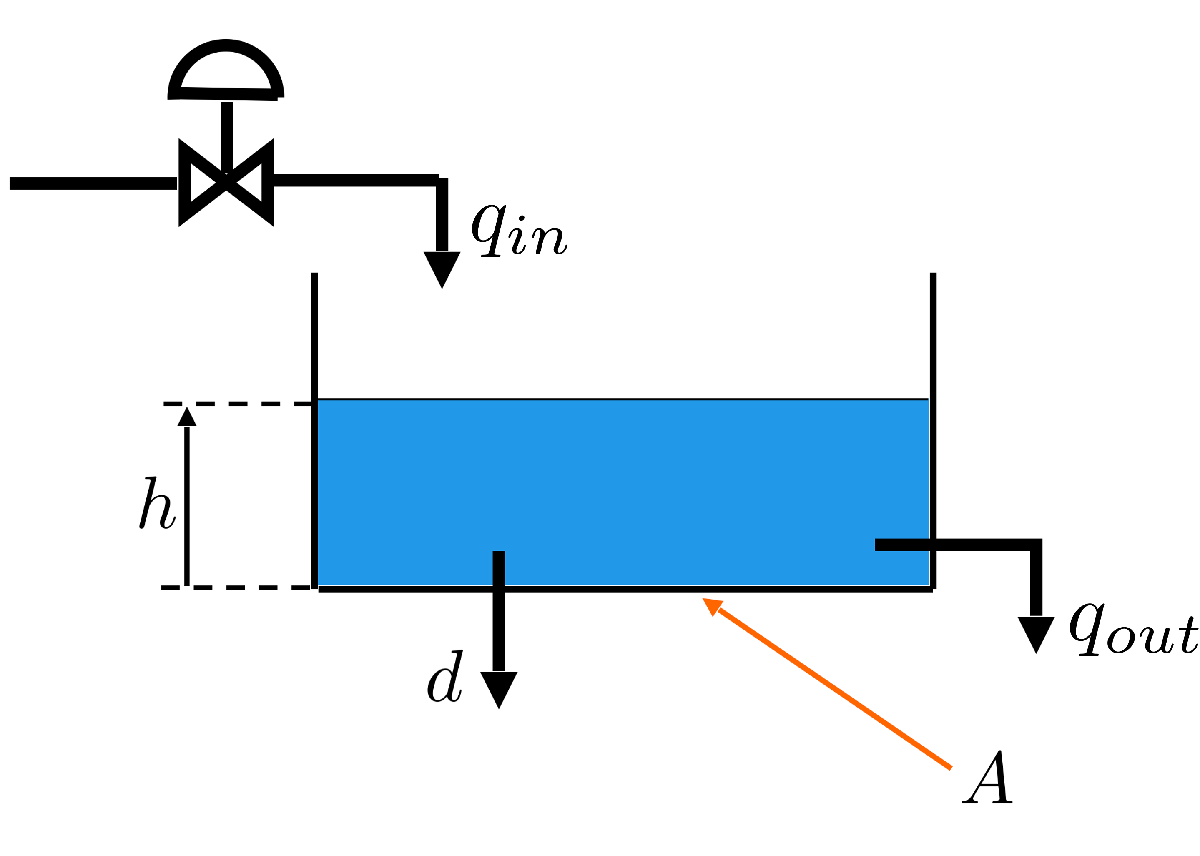

where

- control input: the input flow-rate $q_{in}$

- controlled output: the level of liquid in the tank $h$

- reference output: the constant desired level in the tank $w = h^{o}$

- out-flow rate: $q_{out} = k \cdot h$

- disturbance: $d$

- area of the tank cross-section: $A$

A real system that can be described by the model we are analysing is, for example, a paint mixing tank:

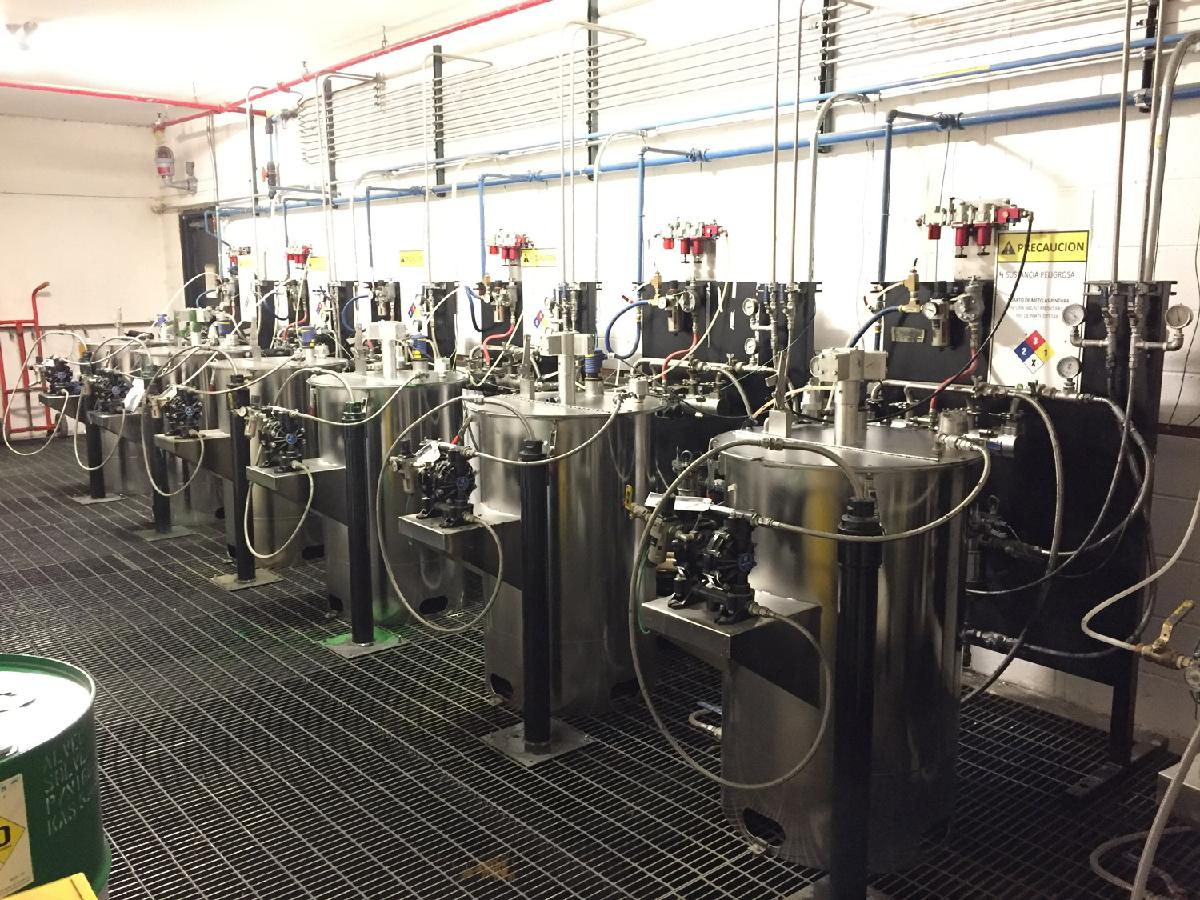

Paint mixing tanks (automotive industry).

Refer to the live scripts  "tank_closedloop_P.mlx " and "tank_closedloop_PI.mlx " in **Part 1** of the course material for a detailed description of the dynamic model for the tank system.

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

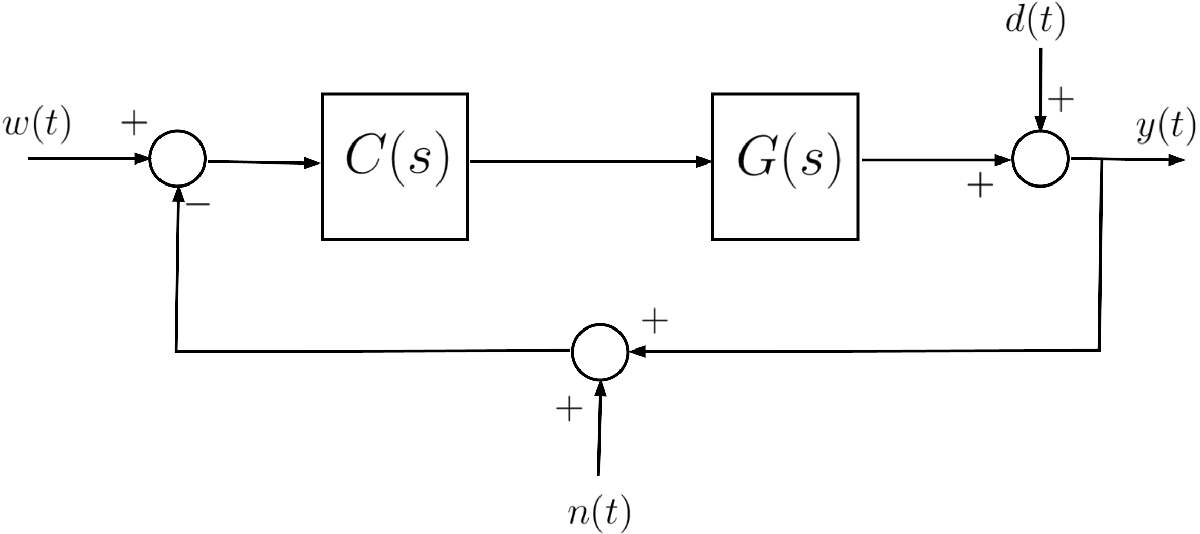	

where $G(s)$ is given by                


$$G(s) = \displaystyle \frac{1}{k} \cdot\frac{1}{1+\displaystyle \frac{A}{k}\,s} = \frac{1}{k+A\,s}$$


with $k$ and $A$ parameters of the tank model.

### Design Requirements

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- the asymptotic value of the error satisfies $\left| e(\infty)\right| =0$, for $w(t) = A\cdot1(t)$, where $1(t)$ denotes the unit step function, and $A \in \mathbb{R}$;

- $t_s \le 5 \,\text{s}$  , where $t_s$ is the settling time at $1\,\%$ ; 

- the phase margin satisfies $\varphi_m \ge 60^{\degree}$

- the crossover frequency $\omega_C$ must be in the set $\omega_C \in \big[1.25\,,\;5.00\big]$ rad/s.

**Q2**:

- let's consider the **discrete-time implementation** of the controller $C(z)$. Thus, **select** a proper **sampling** **period** $T_s$, and using the **Tustin** approximate transformation (or the **Backward** **Euler** one), determine the **difference** **equation** in discrete time that describes the sampled  time algorithm.

## Solution

[](matlab:open('../../TANK_SAMPLED_P_CONTROLLER/tank_closedloop_P_continuous_time.mlx'))

clear % let's clean the Matlab workspace
close all
clc

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))


### System Parameters 

The nominal set of parameters' values is as follows:


$$\begin{array}{rclcrcl}
A&=& 12.34\,\text{m}^2 & \quad & h&=& 0.89 \, \text{m}^2\text{/s} 
\end{array}$$


A = 12.34;  % [m^2] area of the tank section
k = 0.89;   % [m^2/s]  k is the coefficient of the linear law for 
            % calculating the outlet flow rate q_out as a function of the 
            % liquid level h in the tank
            %
            % q_out = k * h
            %


The transfer function of the tank system results

s = tf('s');
Gs = 1/(k+A*s)


Gs =
 
        1
  --------------
  12.34 s + 0.89
 
Continuous-time transfer function.
Model Properties


### Preliminary Analysis

- It is convenient to consider both questions Q1 and Q2, from the beginning of the design procedure.

- The design will be performed at continuous time, taking into account suitable additional margins, so that the original specifications are met with the modified scheme below, considering the digital implementation.

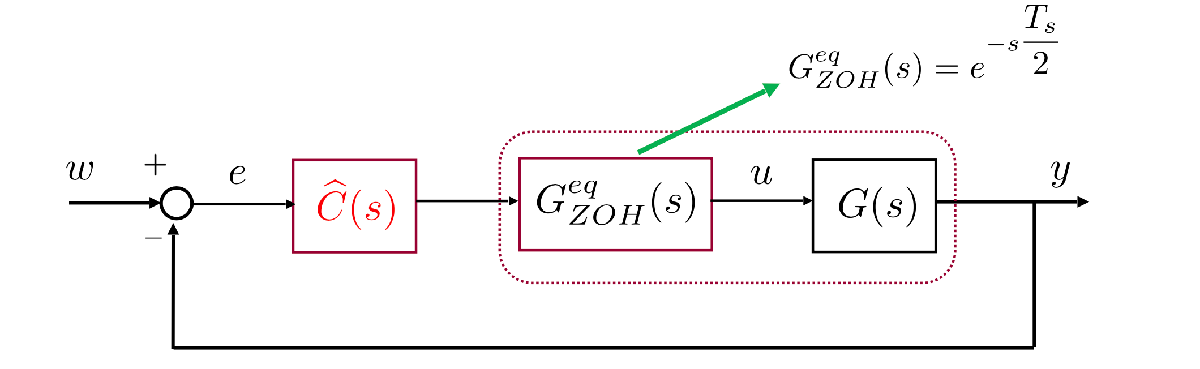

- Hence, we design $\hat C(s)$ such that    $\varphi_m \ge 60^\circ + \delta_\varphi$  where $\delta_\varphi$ is sufficiently large so that the ZOH-induced delay can be accommodated.

### Static Design

According to the requirement (Q1.1), the closed-loop system must be a type $g=1$ system. Thus the static part of the controller must be


$$\hat C_1(s) = \frac{\mu_C}{s}$$


Consider $\hat L(s)$ as the open-loop transfer function without the ZOH-induced delay term


$$\hat L(s) = \mu_C\,\frac{1}{s\,(k+A\,s)}$$


hatLs = Gs/s; % muC = 1

What does the frequency response of such a system look like?

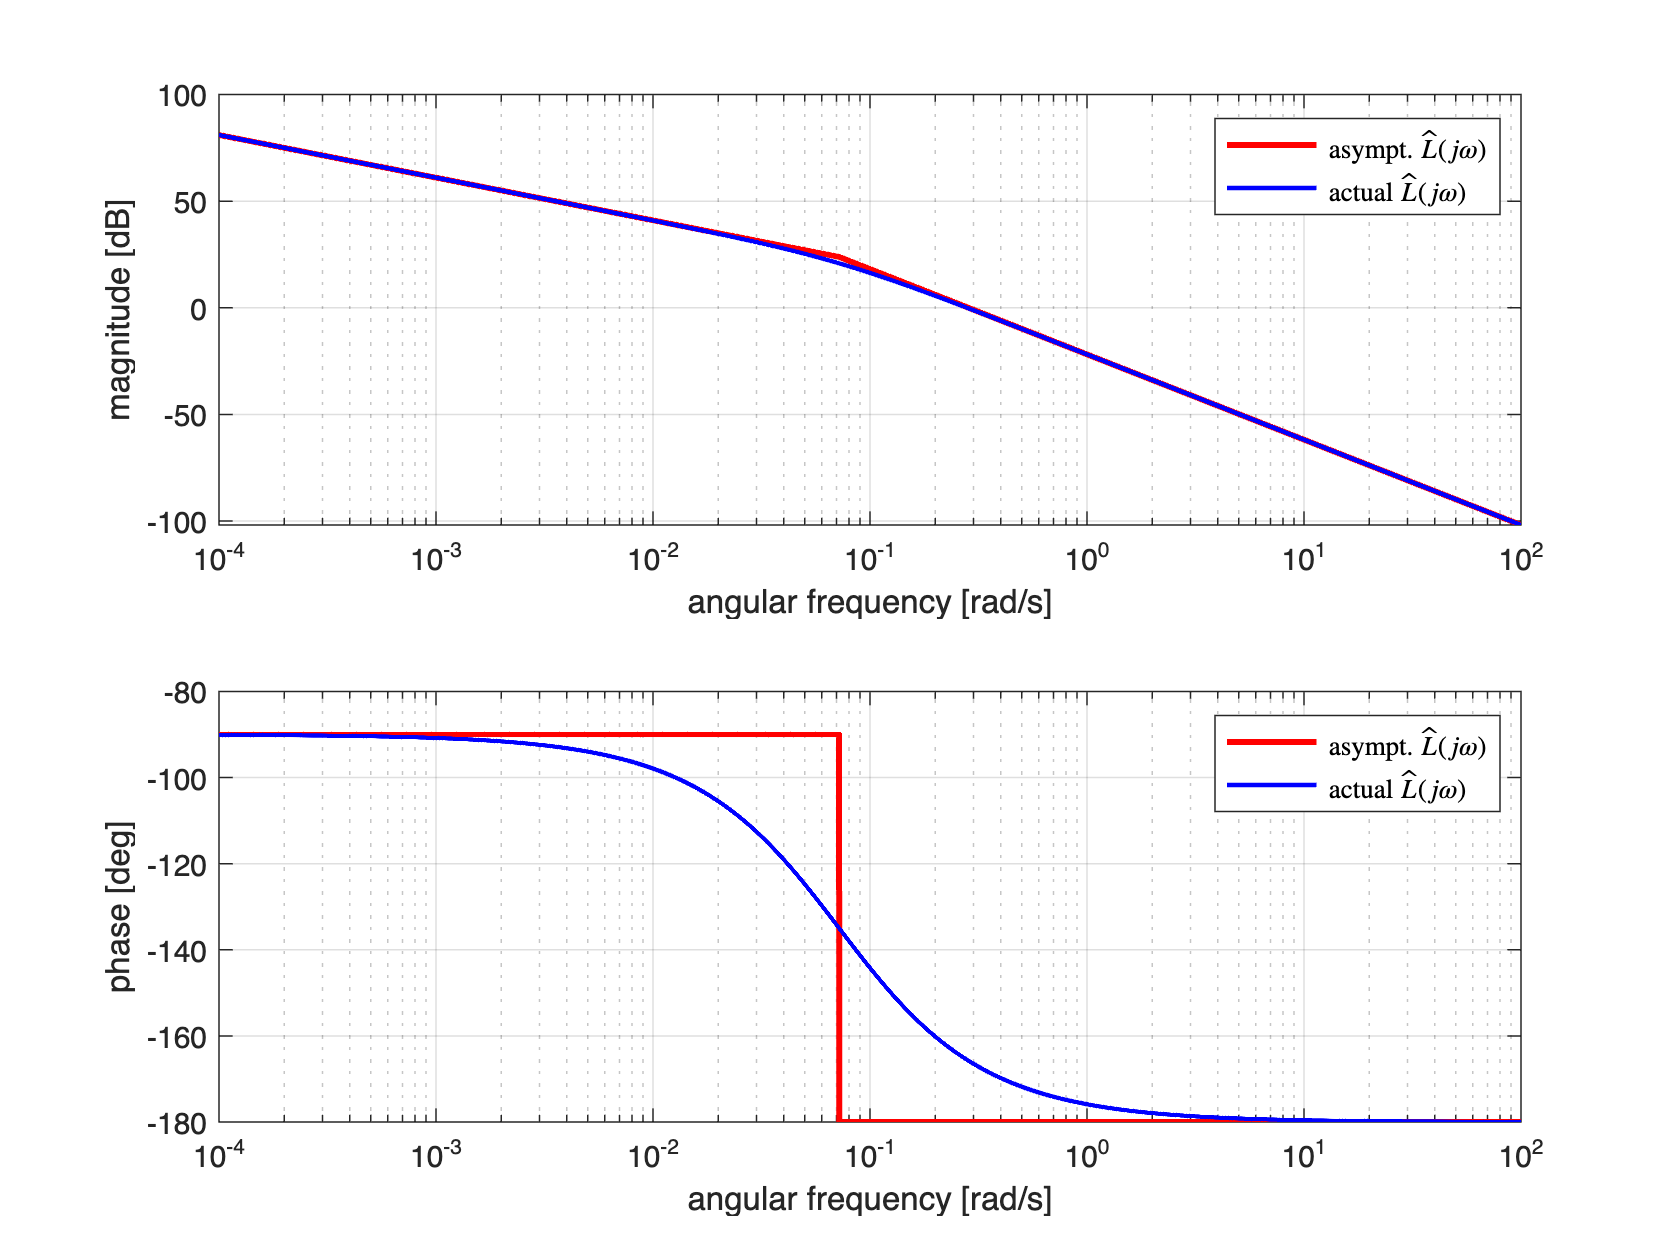

omVALS = logspace(-4,2,1e4);
figure('Units','centimeters','Position',[0.5, 0.5, 27,24]);
[ha1, ha2] = drawBodediagrams(hatLs, omVALS);
legend(ha1, 'asympt. $\hat L(j \omega)$', 'actual $\hat L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $\hat L(j \omega)$', 'actual $\hat L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')

- There is no way to fulfil every requirement, unless we cancel the real pole  of the plant with a zero of the controller. 

- Alternatively, we may add a zero in the transfer function of the controller to increase the phase margin in the set of angular frequencies assigned in (Q1.4).

### Dynamic Design

Let's cancel the plant's pole:


$$\hat C(s) = \mu_C\,\frac{1+\frac{A}{k}\,s}{s} \quad \Longrightarrow \quad \hat L(s) = \frac{\mu_C}{k}\,\frac{1}{s}$$


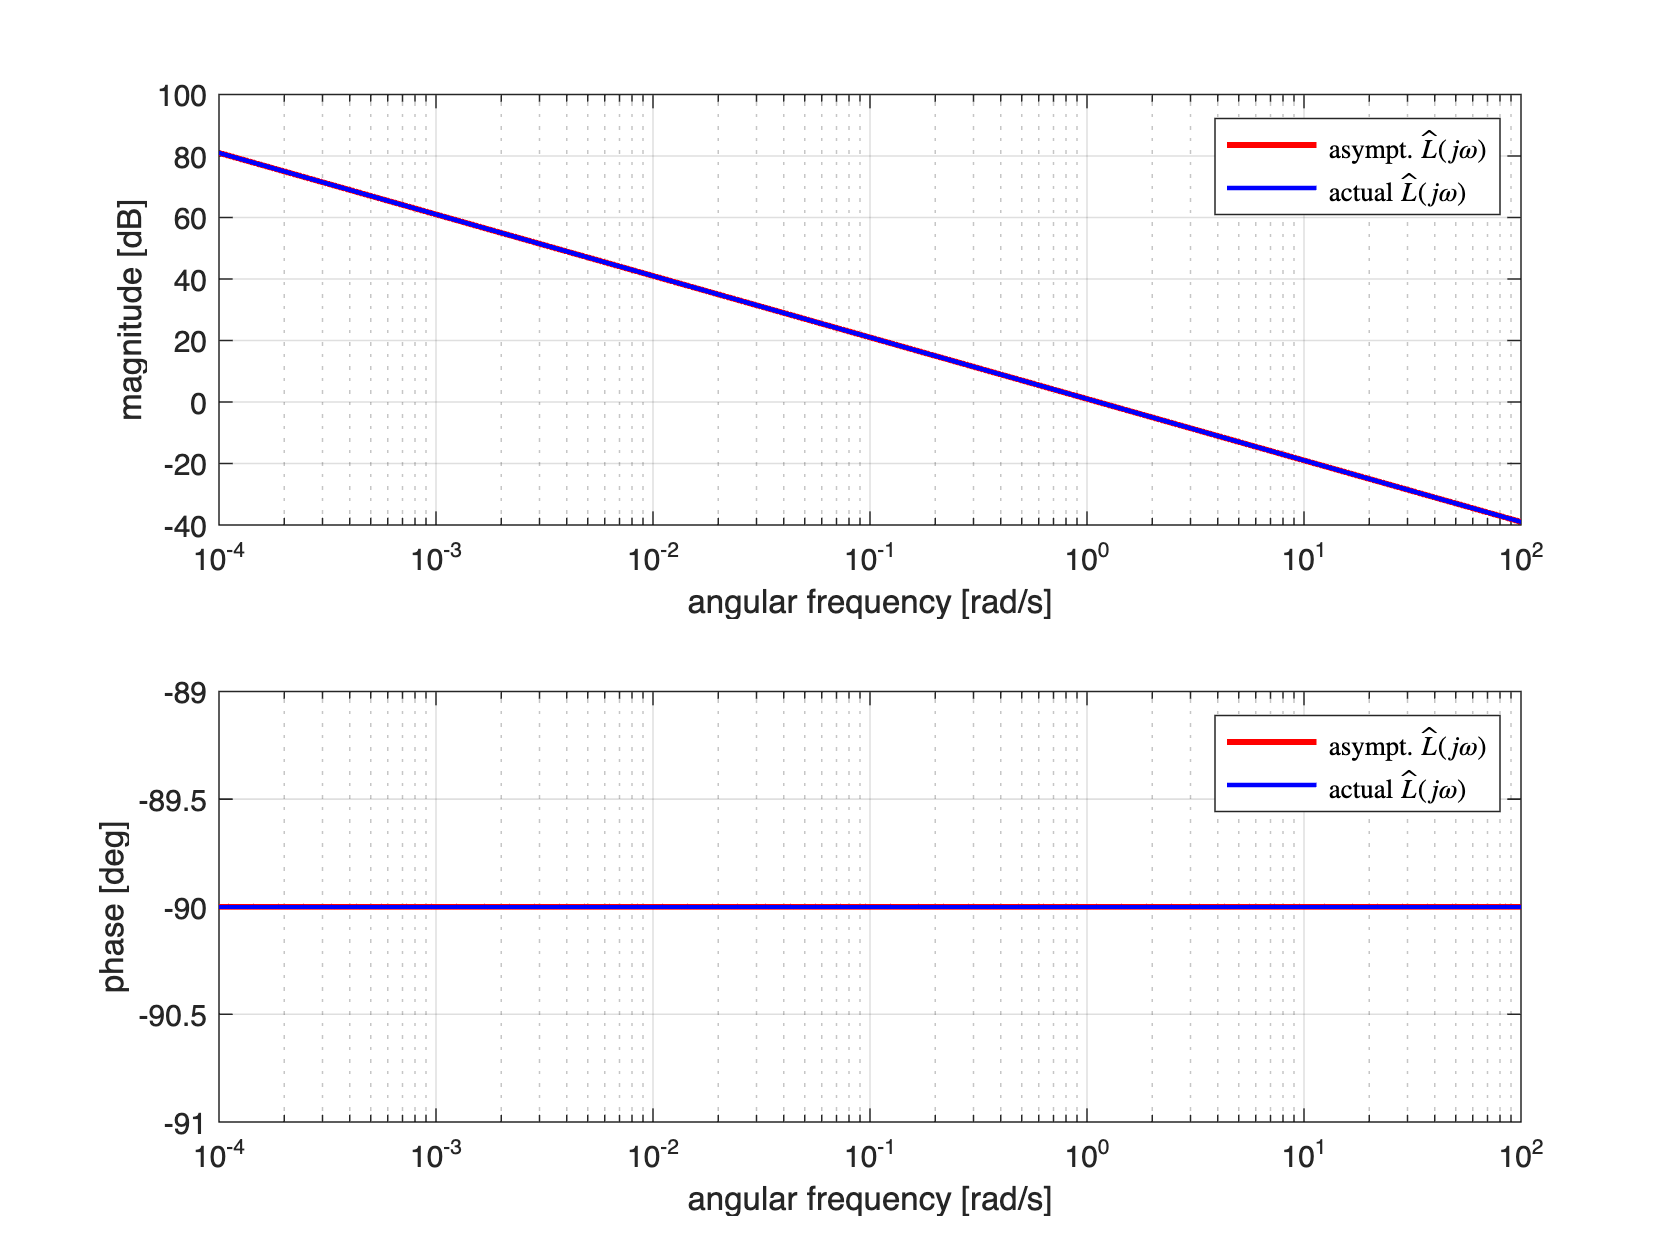

hatLsNEW = 1/k/s; % muC = 1

figure('Units','centimeters','Position',[0.5, 0.5, 27,24]);
[ha1, ha2] = drawBodediagrams(hatLsNEW, omVALS);
legend(ha1, 'asympt. $\hat L(j \omega)$', 'actual $\hat L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $\hat L(j \omega)$', 'actual $\hat L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')

Now, the requirements can be easily met, taking into account the ZOH-induced delay as well.

### Fine Tuning of the Continuous-Time Controller

Set $\omega_C = 4$ and compute the controller gain $\mu_C$:


$$\omega_C=4 \;\Longrightarrow\; \left|\hat L(j \omega_C)\right|=1=\frac{\mu_C}{k\,\omega_C}\; \Longrightarrow \; \mu_C = k\,\omega_C$$


omC = 4;
muC = k*omC

muC = 3.5600

Thus

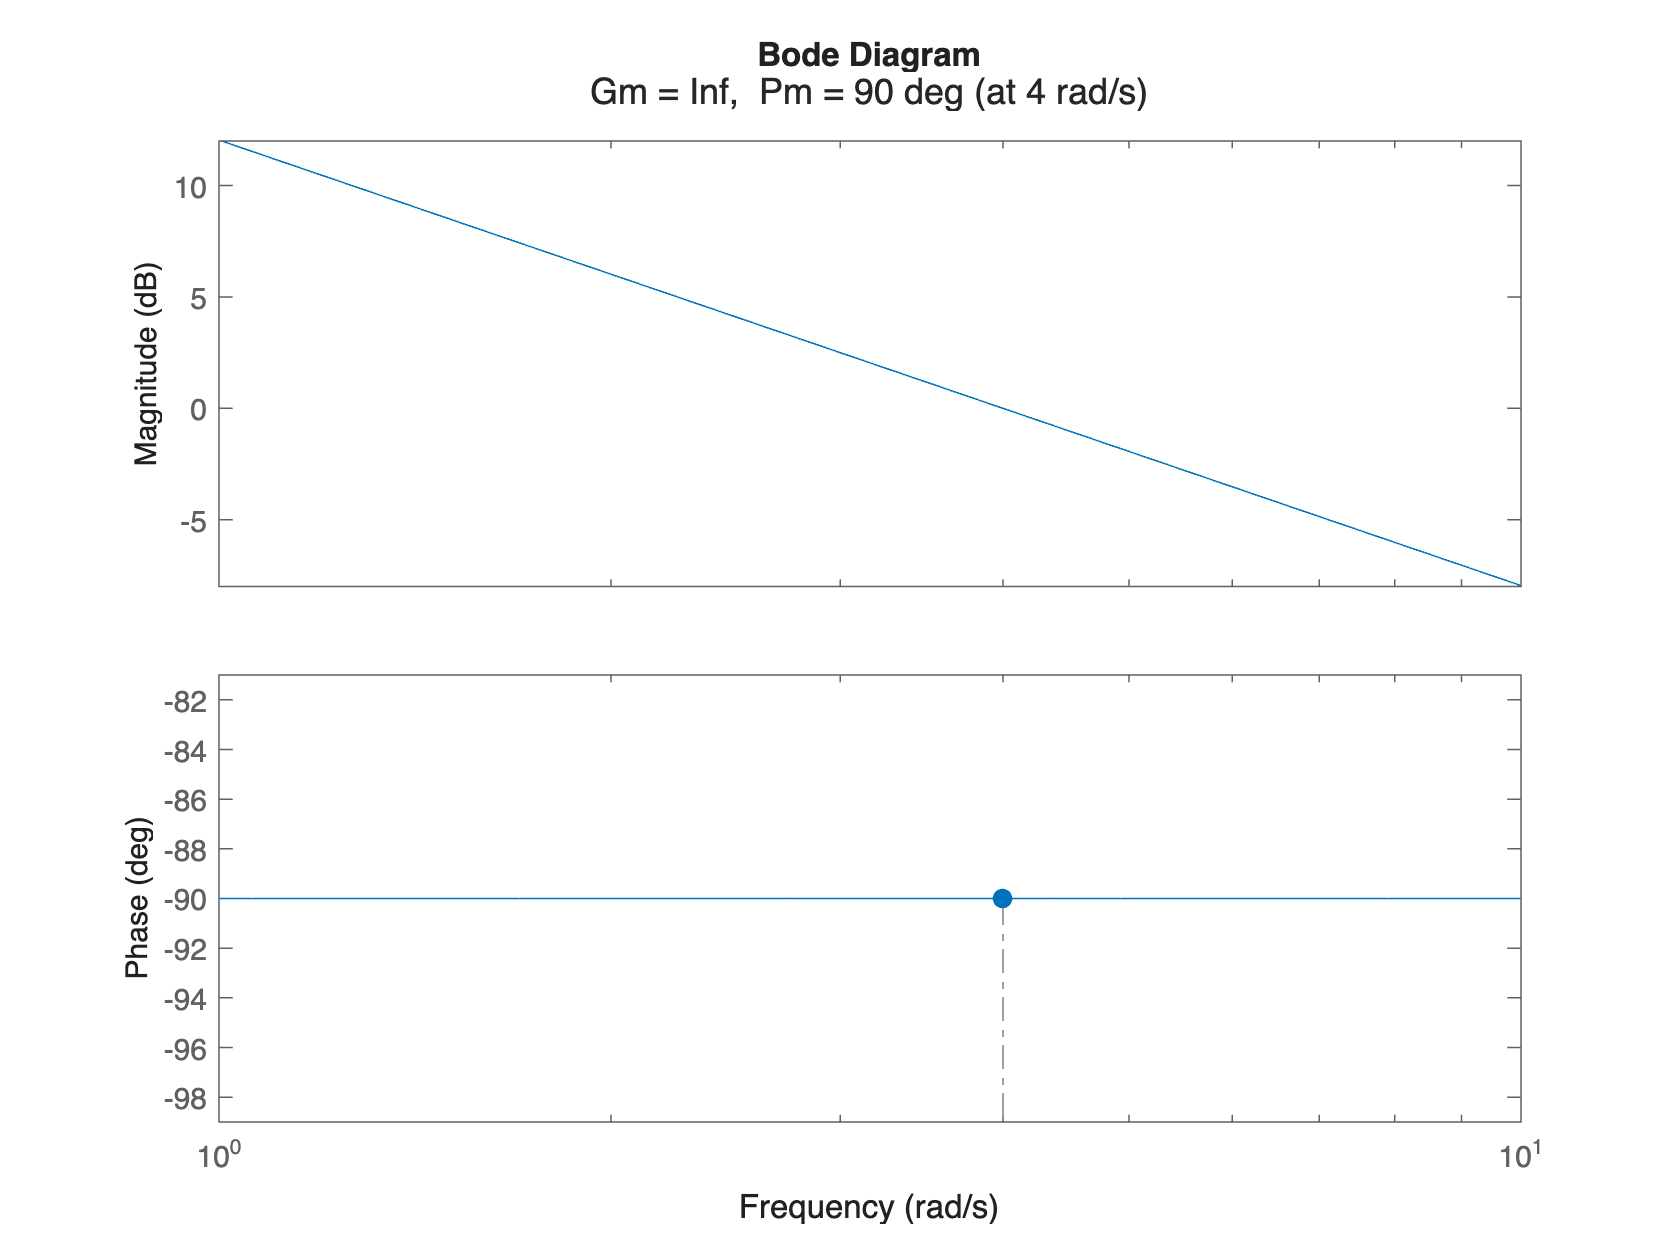

hatLsNEW = muC*hatLsNEW;
figure;margin(hatLsNEW)

### Discretisation of the Controller

Recall the empirical rule on **Slide 60** in **Part 10** of the course material:

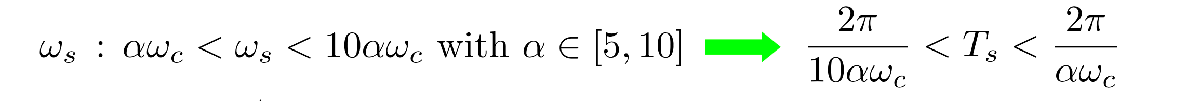

Since $\omega_C = 4$ rad/s


$$\frac{\pi}{20\,\alpha} < T_s < \frac{\pi}{2\,\alpha} \;,\quad \alpha \in \big[5\,,\; 10 \big]$$


MIN_Ts = pi/(20*10)

MIN_Ts = 0.0157


MAX_Ts = pi/(2*5)

MAX_Ts = 0.3142

A suitable choice is


$$T_s = 0.02 \;\text{s}$$


Now

Ts = 0.02;
omSampling = (2*pi)/Ts

omSampling = 314.1593


(0.5*omSampling)/omC

ans = 39.2699

Thus $\omega_C \ll \omega_S$. Hence the effect of the ZOH can be approximated by 


$$G^{eq}_{ZOH}(s) = \displaystyle e^{-s\frac{T_s}{2}} = e^{-\frac{s}{100}$$


which introduces a phase contribution of


$$\delta_{\varphi} = -\frac{\omega_C\,T_s}{2} \cdot \frac{180^\circ}{\pi} = -\frac{4}{100} \cdot \frac{180^\circ}{\pi} \approx 2.3^\circ$$


delta_pm = -((omC*Ts)/2)*(180/pi)

delta_pm = -2.2918

The phase margin becomes $\hat \varphi_m = \varphi_m - \delta_{\varphi} \approx 87.7^{\circ}$

#### The Approximate Transformation

Recall the approximate transformations for the digital controllers on **Slide 66 in Part 10 **of the course material:

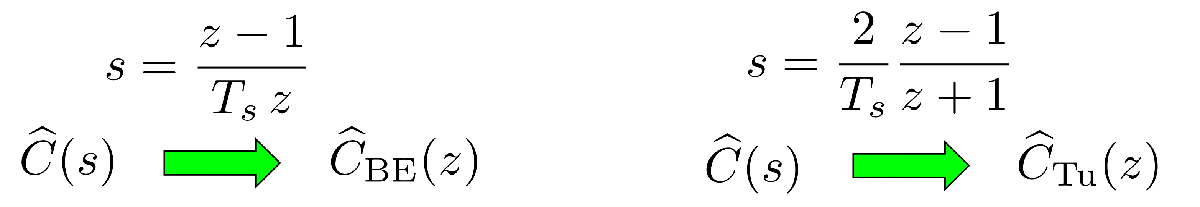

Let's use the Symbolic Math Toolbox to compute the transformation

syms s z 

hatCs = sym(muC)*(1+s*sym(A)/sym(k))/s

$$hatCs = \frac{\frac{1234\,s}{25}+\frac{89}{25}}{s}$$


T_s = sym(Ts);
s2zBE = (z-1)/z/T_s;
s2zTU = (2/T_s)*(z-1)/(z+1);

hatC_BE = collect(simplify(expand(subs(hatCs,s, s2zBE))),z)

$$hatC\_BE = \frac{61789\,z-61700}{1250\,z-1250}$$


hatC_TU = collect(simplify(expand(subs(hatCs,s, s2zTU))),z)

$$hatC\_TU = \frac{123489\,z-123311}{2500\,z-2500}$$

#### From Symbolic Variables to LTI Objects

[numBEsym, denBEsym] = numden(hatC_BE)

$$numBEsym = 61789\,z-61700$$

$$denBEsym = 1250\,z-1250$$


[numTUsym, denTUsym] = numden(hatC_TU)

$$numTUsym = 123489\,z-123311$$

$$denTUsym = 2500\,z-2500$$

Now, let's rewrite the transformed $\hat C(z)$ controllers using the notation with negative powers of $z$

- let's transform the symbolic polynomials into numeric polynomials (of decreasing powers of $z$)

- define the discrete time transfer functions as LTI objects;

- use the notation with dcreasing negative powers of $z$

% ----------------------------------------
% 1) from symbolic to numeric polynomials
%
% the polynomials obtained using the BE transformation
numBE = sym2poly(numBEsym);
denBE = sym2poly(denBEsym);
% the polynomials obtained using the TU transformation
numTU = sym2poly(numTUsym);
denTU = sym2poly(denTUsym);

% --------------------------------------------------------------
% 2) define the discrete time transfer functions as LTI objects
%
% the transformed controller, according to BE
CzBE = tf(numBE, denBE, Ts)


CzBE =
 
  61789 z - 61700
  ---------------
   1250 z - 1250
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties



% the transformed controller, according to TU
CzTU = tf(numTU, denTU, Ts)


CzTU =
 
  123489 z - 123311
  -----------------
    2500 z - 2500
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


For help regarding the MATLAB command tf for describing discrete-time LTI systems, refer to [this page](https://uk.mathworks.com/help/releases/R2024b/control/ref/tf.html?searchPort=53481#mw_997c5170-d392-4325-a4d9-8b038b4863a1).

% ----------------------------------------
% 3) use the notation with dcreasing negative powers of z
BEmonicDenCOEFF = 1/denBE(1); % we would like to transform the polynomial at the denominator 
                            % into a monic polynomial 
CzBEz1 = tf(numBE*BEmonicDenCOEFF, denBE*BEmonicDenCOEFF, Ts, 'variable','z^-1')


CzBEz1 =
 
  49.43 - 49.36 z^-1
  ------------------
       1 - z^-1
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


TUmonicDenCOEFF = 1/denTU(1); % we would like to transform the polynomial at the denominator 
                            % into a monic polynomial 
CzTUz1 = tf(numTU*TUmonicDenCOEFF, denTU*TUmonicDenCOEFF, Ts, 'variable','z^-1')


CzTUz1 =
 
  49.4 - 49.32 z^-1
  -----------------
      1 - z^-1
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


#### The Control Algorithms

Now, using the expressions of the continous-time controller transfer function transformed into sampled-time transfer functions and using also some properties of the Z-transform (refer to **Part 10**, **pp  54-56** and **pp. 72–75** of the course material) we can write the difference equations corresponding to the control algorithms obtained by applying the "Backward Euler" or the "Tustin" transformation rule.

Let's define $U(z)$ and $E(z0$ as the Z-transform of the sampled time control sequence $u[n]$ and the error sequence $e[k]$, respectively. Thus, we can obtain the control sequence $u[n]$ as the output of the sampled-time LTI system named "controller", fed in by the error sequence $e[k]$:


$$U(z) = \hat{C}(z) \, E(z)$$


Now, taking into account that the transformed controller $\hat{C}(z)$ is always (by contruction) a not stricly proper transfer function (i.e., the polynomials at the denominator and numerator both ahve the same degree $n$), we may rearrange the previous expression, as follows


$$U(z) = \hat{C}(z) \, E(z) \quad \Longrightarrow \quad U(z) = \frac{b_0+b_1\,z^{-1}+\cdots +b_n\,z^{-n}}{1+a_1\,z^{-1}+\cdots+a_n\,z^{-n}}\, E(z) \quad \Longrightarrow \quad 
\big(1+a_1\,z^{-1}+\cdots+a_n\,z^{-n} \big)\,U(z) = \big(b_0+b_1\,z^{-1}+\cdots +b_n\,z^{-n} \big)\,E(z)$$


**Important Remarks**

- both polynomials are expressed using decreasing powers of $z^{-1}$ ;

- It's helpful to write the polynomial in the denominator in such a way that the coefficient $a_0$ is equal to $+1$.

Now, exploiting the properties of the Z-transform, we obtain the **control** **algorithm**, described as a **difference** **equation**:


$$\big(1+a_1\,z^{-1}+\cdots+a_n\,z^{-n} \big)\,U(z) = \big(b_0+b_1\,z^{-1}+\cdots +b_n\,z^{-n} \big)\,E(z) \;\Longrightarrow \; u[k] + a_1\,u[k-1] + \cdots +a_n\,u[k-n] = b_0\,e[k]+b_1\,e[k-1]+\cdots +b_n\,e[k-n]$$


Rearranging the difference equation, the control algorithm results


$$u[k] = -u[k] - a_1\,u[k-1] - \cdots -a_n\,u[k-n] + b_0\,e[k]+b_1\,e[k-1]+\cdots +b_n\,e[k-n]$$


Applying the **BE Transformation**, the **control** **algorithm** becomes:


$$\big(1-\,z^{-1} \big)\,U(z) = \big(49.43 - 49.36\,z^{-1} \big)\,E(z) \quad \Longrightarrow \quad 
u[k] = u[k-1] + 49.43\,e[k]-49.36\,e[k-1]$$


Using the **Tu** **approximation**, the **control** **algorithm** is:


$$\big(1-\,z^{-1} \big)\,U(z) = \big(49.40 - 49.32\,z^{-1} \big)\,E(z) \quad \Longrightarrow \quad 
u[k] = u[k-1] + 49.40\,e[k]-49.32\,e[k-1]$$
